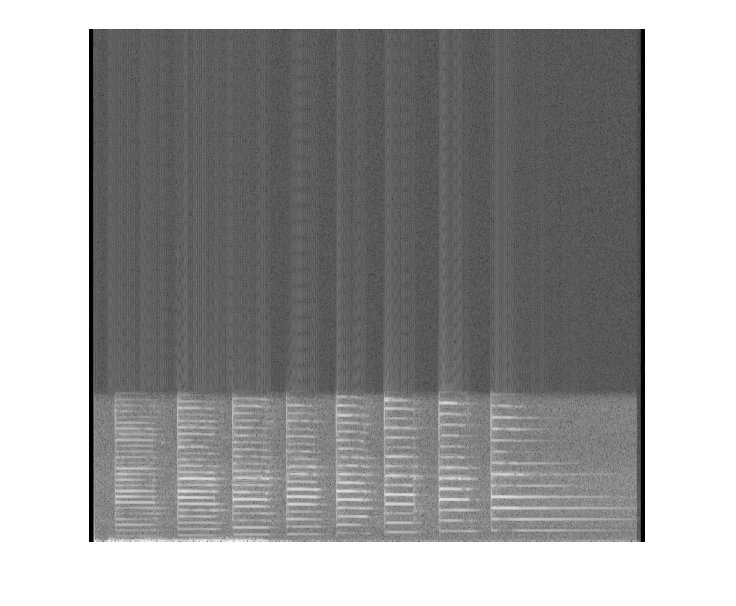

[x,fs] = audioread('NotasMusicais.wav');                        %Carrega o audio e frequencia de amostragem
duracao = length(x);
[X, freq_pico]  = calcula_espectrograma(x,fs,duracao);
%sound(x*.5,fs)                                                  %toca o som
imshow(X.^0.1);                                                 %Mostra o espectrograma e aumenta o contraste para melhorar a visualização

O primeiro caso de teste foi para um arquivo de audio que contem uma sequencia completa de notas, sendo que a nota Dó no final foi tocada ate o som se extinguir e sua frequência de pico foi de:

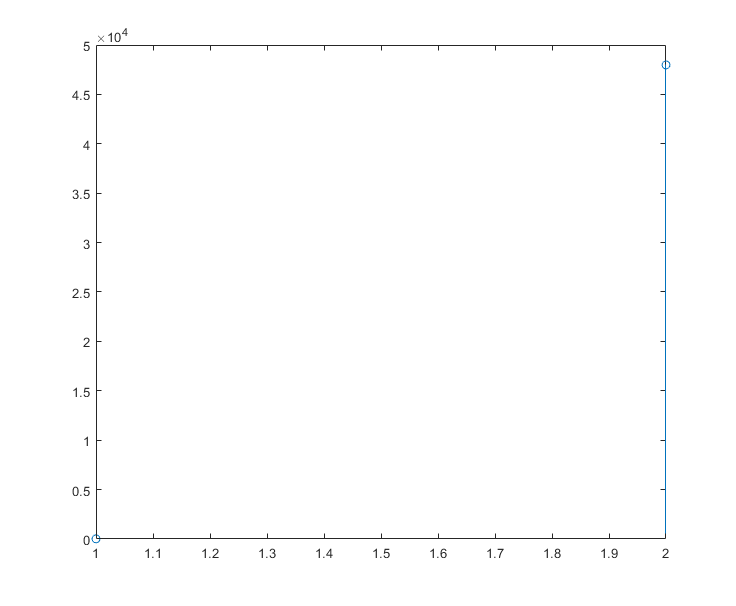

stem(freq_pico);

Este audio contém duas amostras com mesma amplitude e por isso a frequencia de pico gerou um vetor com duas amostras também

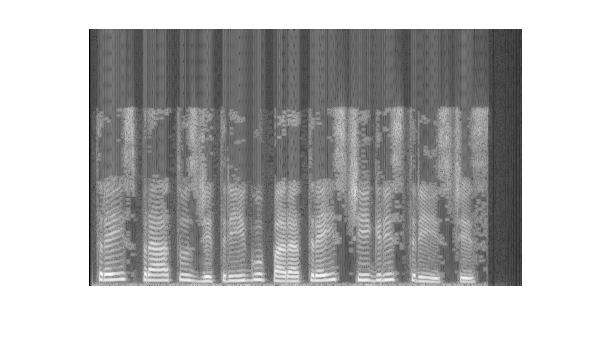

[x,fs] = audioread('TigreTriste.wav');                        %Carrega o audio e frequencia de amostragem
duracao = length(x);
[X, freq_pico]  = calcula_espectrograma(x,fs,duracao);
%sound(x*.5,fs)                                                  %toca o som
imshow(X.^0.1);  

Este caso de teste foi para um arquivo de audio que contem uma pessoa dizendo "Três pratos de trigo para três tigres tristes"  e sua frequência de pico foi de:

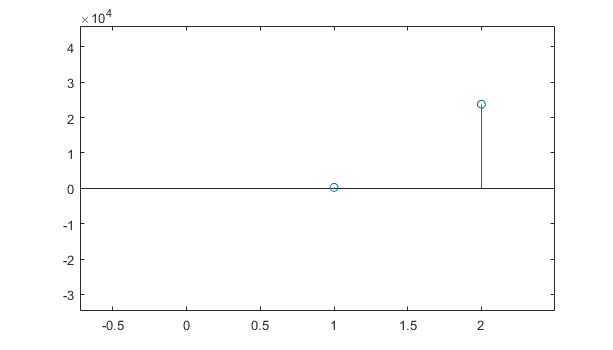

stem(freq_pico);

function [X, freq_pico]  = calcula_espectrograma(x,fs,duracao)
    
    [L, C] = size(x);
    if C == 2
        x = (x(:,1) + x(:,2))/2;                            %Verifica se o arquivo é estereo e converte para mono
    end
    
    %Calculo da frequencia de pico
    SpecAmpX = abs(fft(x));                                 %Pegando a resposta em amplitude da DFT
    valor_maximo = max(SpecAmpX);                           %Define qual a amostra com maior amplitude
    posicao = find(SpecAmpX ==valor_maximo);                %Encontra onde está localizada esta amostra
    freq_pico = (posicao - 1) * fs / duracao;               %Calcula a frequencia de pico
    
    %Geração do espectrograma
    x = x';                                                 %Transpoe o vetor
    std(x);                                                 %calculo de potencia do sinal "Desvio padrão"
    x = x/10;                                               %Diminui a amplitude
    N = 0.020;                                              %muda a escala da imagem
    X = spectrogram(x,round(N*fs));                         %Aplica a STFT ao sinal de entrada para gerar o espectrograma
    X = X/max(abs(X(:)));                                   %Normaliza para poder ser representado como imagem
    X = flipud(X);                                          %Inverte verticalmente a imagem
    X = abs(X);                                             %Pega o módulo da imagem para mostrar o espectro de amplitude

    
    
end